# Distribution fitting

close all
clear all
clc

## Depth 2


% data = readstruct('depth2.json');
% data2 = data.x2;
% histogram(data2);
% hold on
% [x2, y2, fit2] = allfits(data2);
% plot(x2, y2.*10000, 'LineWidth', 1)
% plot(fit2)
% legend('Depth 2 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
% xlabel('Turns to Win [#]')
% ylabel('Quantity [#]')


## Depth 3

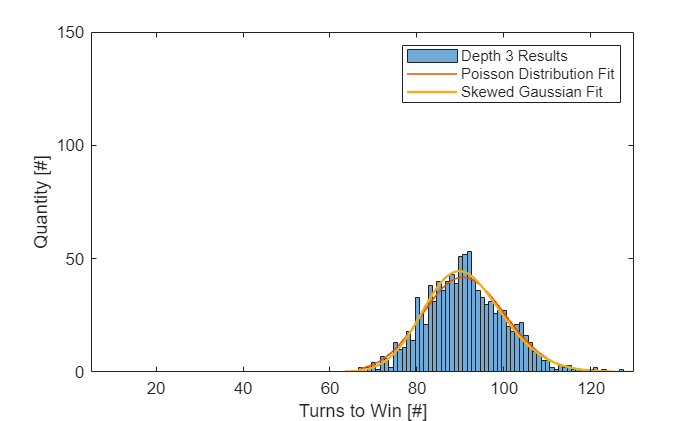

hold off
data = readstruct('depth3.json');
data3 = data.x3;
histogram(data3, 61);
hold on
[x3, y3, fit3] = allfits(data3);
plot(x3, y3.*1000, 'LineWidth', 1)
plot(fit3)
legend('Depth 3 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth3.jpg');

## Depth 4

hold off

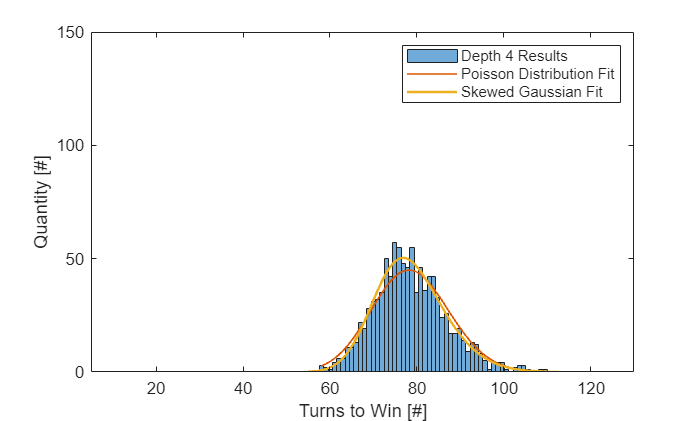

data = readstruct('depth4.json');
data4 = data.x4;
histogram(data4, 53);
hold on
[x4, y4, fit4] = allfits(data4);
plot(x4, y4.*1000, 'LineWidth', 1)
plot(fit4)
legend('Depth 4 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth4.jpg');

## Depth 5

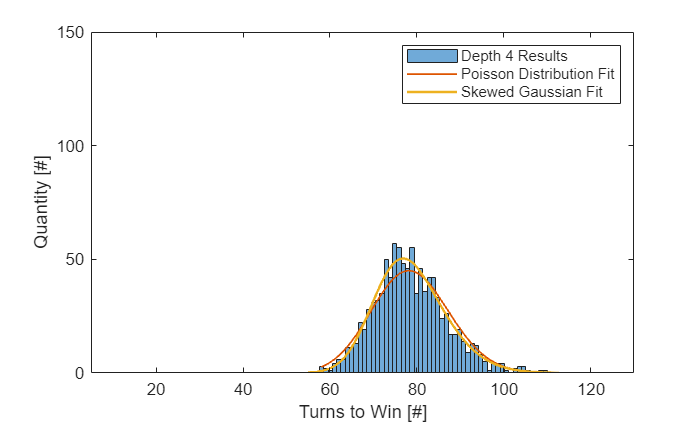

hold off

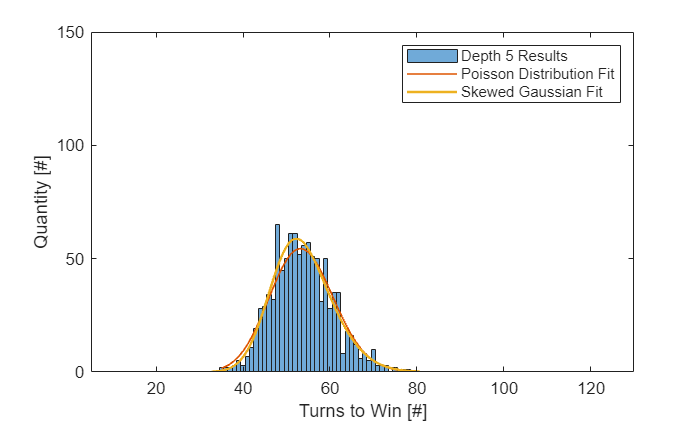

data = readstruct('depth5.json');
data5 = data.x5;
histogram(data5);
hold on
[x5, y5, fit5] = allfits(data5);
plot(x5, y5.*1000, 'LineWidth', 1)
plot(fit5)
legend('Depth 5 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth5.jpg');

## Depth 6

hold off

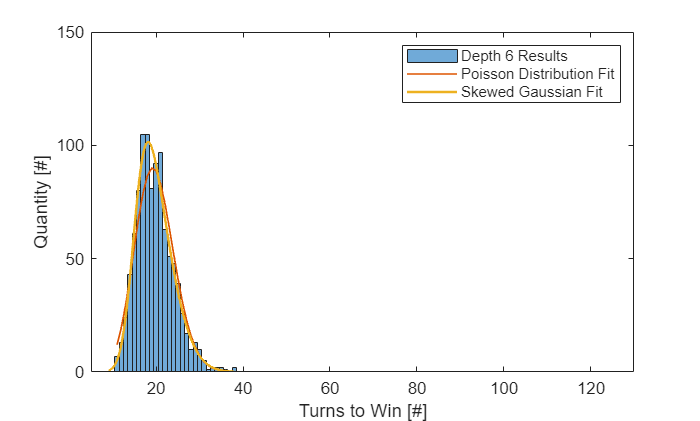

data = readstruct('depth6.json');
data6 = data.x6;
histogram(data6);
hold on
[x6, y6, fit6] = allfits(data6);
plot(x6, y6.*1000, 'LineWidth', 1)
plot(fit6)
legend('Depth 6 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth6.jpg');

## Depth 7

hold off

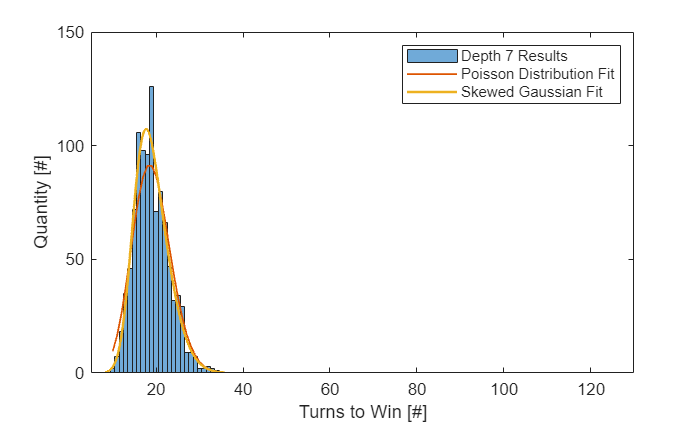

data = readstruct('depth7.json');
data7 = data.x7;
histogram(data7);
hold on
[x7, y7, fit7] = allfits(data7);
plot(x7, y7.*1000, 'LineWidth', 1)
plot(fit7)
legend('Depth 7 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth7.jpg');

## Depth 8

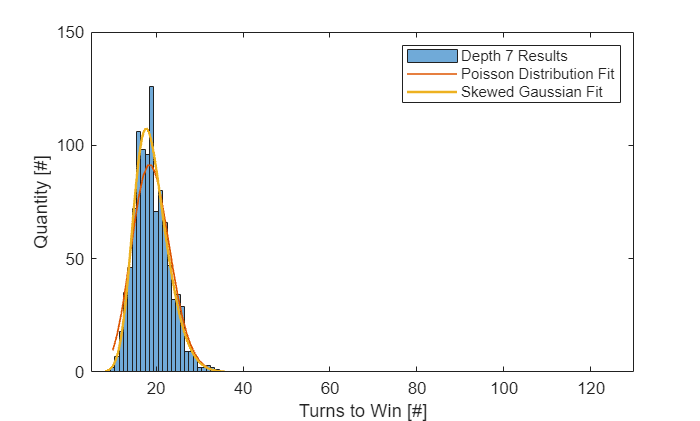

hold off

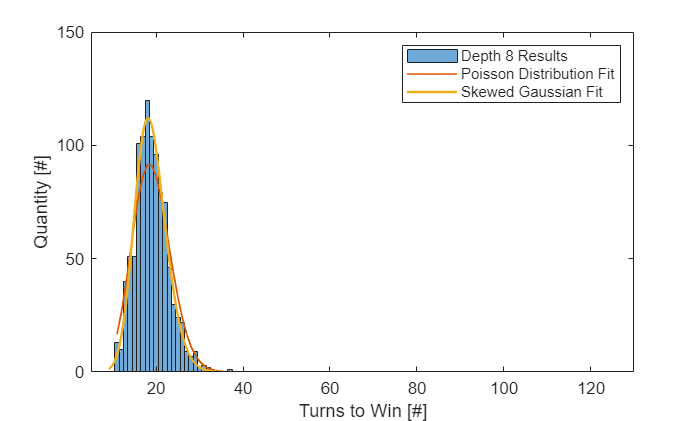

data = readstruct('depth8.json');
data8 = data.x8;
histogram(data8);
hold on
[x8, y8, fit8] = allfits(data8);
plot(x8, y8.*1000, 'LineWidth', 1)
plot(fit8)
legend('Depth 8 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth8.jpg');

## Depth 9

hold off

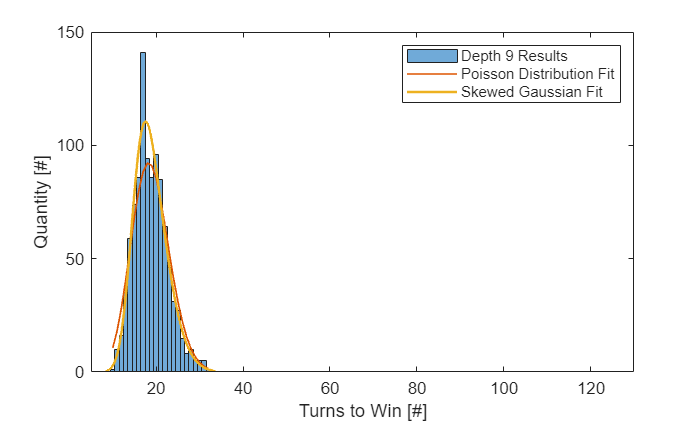

data = readstruct('depth9.json');
data9 = data.x9;
histogram(data9);
hold on
[x9, y9, fit9] = allfits(data9);
plot(x9, y9.*1000, 'LineWidth', 1)
plot(fit9)
legend('Depth 9 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth9.jpg');

## Depth 10

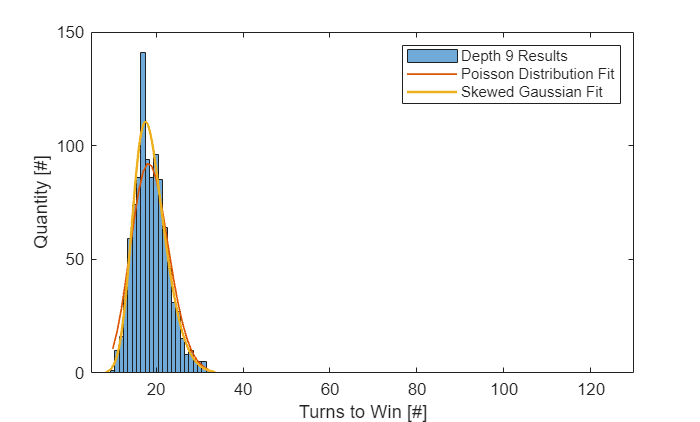

hold off

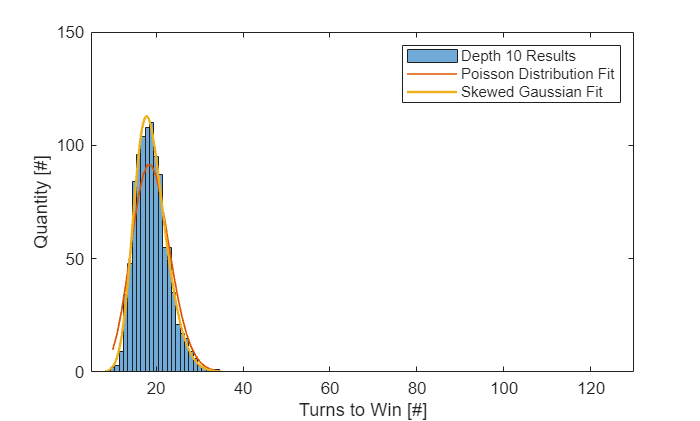

data = readstruct('depth10.json');
data10 = data.x10;
histogram(data10);
hold on
[x10, y10, fit10] = allfits(data10);
plot(x10, y10.*1000, 'LineWidth', 1)
plot(fit10)
legend('Depth 10 Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
xlim([5 130])
ylim([0 150])
saveas(gcf, 'depth10.jpg');

## Extra runs Depth 6

hold off

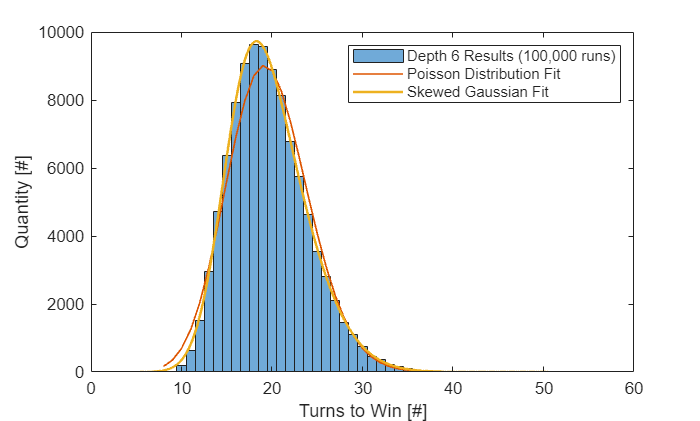

data = readstruct('depth6_deep.json');
data9 = data.x6;
histogram(data9);
hold on
[x6deep, y6deep, fit6deep] = allfits(data9);
plot(x6deep, y6deep.*100000, 'LineWidth', 1)
plot(fit6deep)
legend('Depth 6 Results (100,000 runs)', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
saveas(gcf, 'depth6deep.jpg');

## Neural Deep

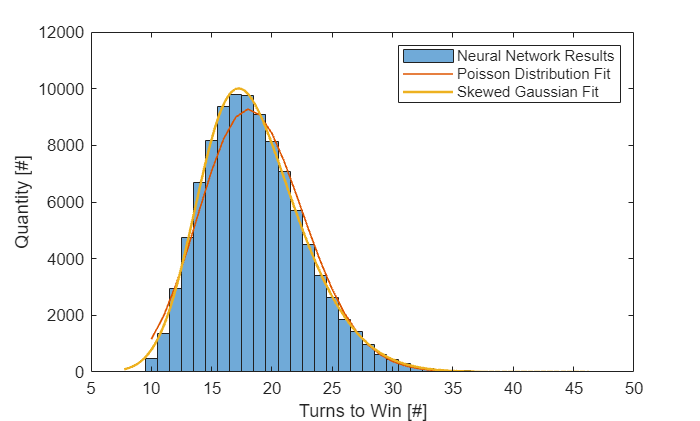

hold off

data = readstruct('neural_deep.json');
data_neural = data.turns;
histogram(data_neural);
hold on
[x6deep, y6deep, fit6deep] = allfits(data_neural);

pHat = 18.5650

CI =    18.5383
   18.5917


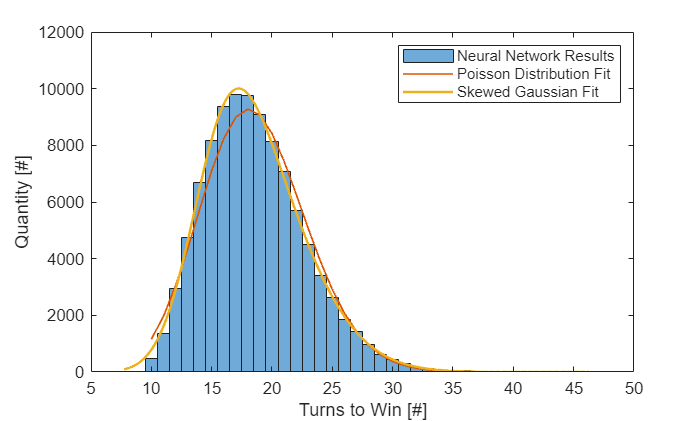

plot(x6deep, y6deep.*100000, 'LineWidth', 1)
plot(fit6deep)
legend('Neural Network Results', 'Poisson Distribution Fit', 'Skewed Gaussian Fit')
xlabel('Turns to Win [#]')
ylabel('Quantity [#]')
saveas(gcf, 'neuralDeep.jpg');

## Functions

   
function [x, y, skewfit] = allfits(data, alpha) 
    arguments
        data
        alpha = 0.05; % Default value is 95% confidence interval
    end

    Min = min(data);
    Max = max(data);
    nbins = Max - Min + 1;


[N,edges,bin] = histcounts(data, nbins);
% Poission model
[pHat, CI] = poissfit(data, alpha);

x = Min:Max; % Range of possible events
y = poisspdf(x, pHat); % Compute poisson PDF

% Skewed gaussian model
skewedGauss = fittype(@(a, b, c, alpha, x) 2*a*exp(-((x-b).^2)/(2*c^2)) .* normcdf(alpha*(x-b)/c), ...
    'independent', 'x', 'dependent', 'y');

% Setting initial guesses [amplitude, mean, std_dev, skewness]
startPoints = [max(N), mean(x), std(x), 0.0118];

% Fitting the data to the skewed gaussian
[skewfit, gof] = fit(x(:), N(:), skewedGauss, 'Start', startPoints);

end

